% plotting signals
[signal,fs] =  audioread('Audio.wav');
plot(signal)
xlabel('t');% plotting signals
[signal,fs] =  audioread('Audio.wav');
plot(signal)
xlabel('t');
ylabel('AudioFile[t]');
title('AudioFileProcessing');
[signalFourierTransform,frequency] = standardFourierTransform(signal,fs);
figure()
plot(frequency,abs(signalFourierTransform));
title('SignalFourierTrans');
xlabel('frequency');
ylabel('magnitude');
% calculating BW of 99 percent.
[audioDataSdf,audioDataFourierTransform] = sdf(transpose(signal));

domain = linspace(-pi,pi,size(frequency,2));
finalDomain = (domain/(2*pi))*fs;

powerAbs = abs(audioDataSdf);
totalEnergy = sum(powerAbs);
maxPower = max(powerAbs);
peakEnergy = find(powerAbs == maxPower);
centerFrequency = mean(peakEnergy);
power99 = totalEnergy*0.99;
freqIterator = 10;% 1kHz
boundedEnergy = calEnergy(powerAbs,centerFrequency,freqIterator);
while boundedEnergy < power99
    freqIterator = freqIterator + 1;
    boundedEnergy = calEnergy(powerAbs,centerFrequency,freqIterator);
end
startBound = centerFrequency - freqIterator;
endBound = centerFrequency + freqIterator;
normalizedStartBound = finalDomain(startBound:endBound);
SignalBW = ((normalizedStartBound(end)) - (normalizedStartBound(1)))/2
cutSignal = zeros(1,size(normalizedStartBound,2));
cutSignal(1:end) = powerAbs(startBound:endBound);
figure
plot(normalizedStartBound,cutSignal)
xlabel('frequency');
ylabel('AudioDataEnergy(f)');
title('AudioFileProcessing');
% finding good fm
% playing original voice
sound(signal,fs);

% for i = 1:20
%     SignalBW
%     test = lowpass(signal,SignalBW+i*250 ,fs);
%     sound(test,fs);
% end
% my Deaf ear's Best suggestion :

test = lowpass(signal,6000,fs);
sound(test,fs);

% lowpass with F_cut = SignalBW = 2.6k
test = lowpass(signal,SignalBW,fs);
sound(test,fs);

% filtering signal with real lowpass filter that we designed
load('lowPassFm.mat');
signalFilter = filter(lowPassFm,1,signal);
sound(signalFilter,fs);
[filteredSignal,freq] = standardFourierTransform(signalFilter,fs);
plot(freq,abs(filteredSignal));
title('signalAfterFilter');
xlabel('frequency');
ylabel('magnitude');
% upsampeling filtered signal
upsampling = 10;
Fs = fs*upsampling;
upsampledSignal = interp(signalFilter,upsampling);
[upsampledSignalFourierTransform,frequency] = standardFourierTransform(upsampledSignal,Fs);
plot(frequency,abs(upsampledSignalFourierTransform));
title('upsampledFourierSignal');
xlabel('frequency');
ylabel('magnitude');
% creating modulated signal
t = 1/Fs:1/Fs:length(upsampledSignal)/Fs;
signalIntegral = Integral(upsampledSignal,Fs);
fm = 6500;
max_signal = max(upsampledSignal);
B = 3;
fc = 50000;
fdelta = B*fm/max_signal;
Xc = cos(2*pi*fc*t + 2*pi*fdelta*signalIntegral);
[XcFourierTransform,freq] = standardFourierTransform(Xc,Fs);
plot(freq,abs(XcFourierTransform));
title('XcFourierTransform');
xlabel('frequency');
ylabel(' Magnitude');
% demodelig signal
derivativeSignal = derivative(Xc,Fs);
[derivativeSignalFourierTransform,freq] = standardFourierTransform(derivativeSignal,Fs);
plot(freq,abs(derivativeSignalFourierTransform));
title('derivativeSignalFourierTransform');
xlabel('frequency');
ylabel('Magnitude');
signalabs = abs(derivativeSignal);

[signalAbsFourierTransform,freq] = standardFourierTransform(signalabs,Fs);
plot(freq,abs(signalAbsFourierTransform));
title('AfterAbsSignalFourierTransform');
xlabel('frequency');
ylabel('Magnitude');

dcBlocker = dsp.DCBlocker;
dcRemovedSignal = dcBlocker(transpose(signalabs));
[dcRemovedFourierTransform,freq] = standardFourierTransform(dcRemovedSignal,Fs);
plot(freq,abs(dcRemovedFourierTransform));
title('dcRemovedFourierTransform');
xlabel('frequency');
ylabel(' Magnitude');
% filtering demodulated
load('DemodLPF.mat');
demodulatedSignal = filter(DemodLPF,1,dcRemovedSignal);
[demodulatedFourierTransform,freq] = standardFourierTransform(demodulatedSignal,Fs);
plot(freq,abs(demodulatedFourierTransform));
title('AfterLPF');
xlabel('frequency');
ylabel(' Magnitude');
% downsampling signal ...
demodulatedDownSample = downsample(demodulatedSignal,upsampling);

gain = 1/(4*fdelta);
% removing DC 
demoduleDCLess = dcBlocker(demodulatedDownSample);
demoduleDCLess = gain*demoduleDCLess;
[demoduleDCFourierTransform,freq] = standardFourierTransform(demoduleDCLess,fs);
plot(freq,abs(demoduleDCFourierTransform));
title('FinalDemodulatedSignal');
xlabel('frequency');
ylabel(' Magnitude');
sound(demoduleDCLess,fs);
DemoduleVsInputError = immse(abs(signalFourierTransform),abs(demoduleDCFourierTransform))

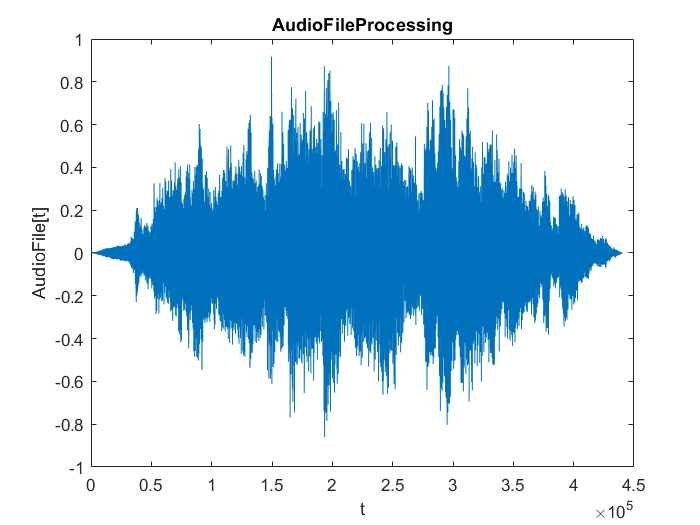

function [out,standardDomain] = standardFourierTransform(signal,fs)
n = length(signal);
fourier=fft(signal,n);
fourier = fourier/fs;
out = fftshift(fourier);
domain = linspace(-pi,pi,length(out));
standardDomain = domain*fs/(2*pi);
end

function [out,Tsignal] = sdf(signal)
Tsignal = fourierDiscreteStandardTransform(signal);
out = Tsignal.*conj(Tsignal);
end

function out = fourierDiscreteStandardTransform(signal)
out = fftshift(fft(signal,size(signal,2)));
end

function boundedEnergy = calEnergy(powerSignal,center,range)
boundedEnergy = sum(powerSignal(center-range:center+range));
end


function integral = Integral(signal,fs)
integral = zeros(1,length(signal));
for i = 2 : length(signal)
    integral(1,i) = integral(1,i-1) + ( signal(i) + signal(i-1) )/(2*fs);
end
end


function derive = derivative(signal,fs)
derive = zeros(1,length(signal));
for i=2:length(signal)-1
    derive(i) = (signal(i+1)-signal(i-1))*fs/2;
end
end

ylabel('AudioFile[t]');
title('AudioFileProcessing');

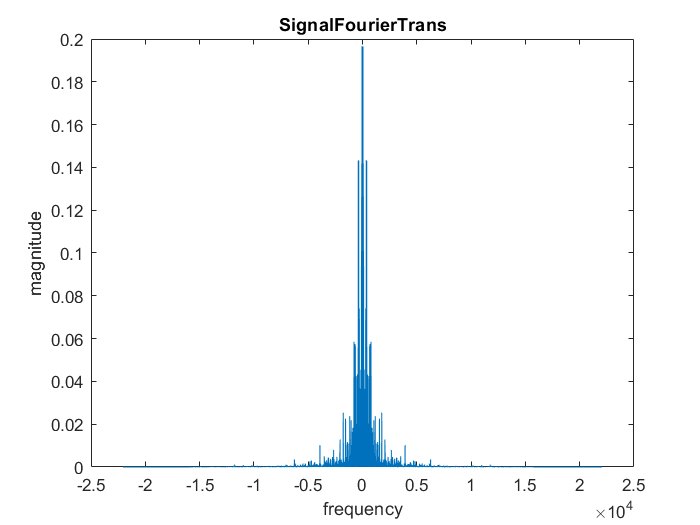

[signalFourierTransform,frequency] = standardFourierTransform(signal,fs);
figure()
plot(frequency,abs(signalFourierTransform));
title('SignalFourierTrans');
xlabel('frequency');
ylabel('magnitude');

% calculating BW of 99 percent.
[audioDataSdf,audioDataFourierTransform] = sdf(transpose(signal));

domain = linspace(-pi,pi,size(frequency,2));
finalDomain = (domain/(2*pi))*fs;

powerAbs = abs(audioDataSdf);
totalEnergy = sum(powerAbs);
maxPower = max(powerAbs);
peakEnergy = find(powerAbs == maxPower);
centerFrequency = mean(peakEnergy);
power99 = totalEnergy*0.99;
freqIterator = 10;% 1kHz
boundedEnergy = calEnergy(powerAbs,centerFrequency,freqIterator);
while boundedEnergy < power99
    freqIterator = freqIterator + 1;
    boundedEnergy = calEnergy(powerAbs,centerFrequency,freqIterator);
end
startBound = centerFrequency - freqIterator;
endBound = centerFrequency + freqIterator;
normalizedStartBound = finalDomain(startBound:endBound);
SignalBW = ((normalizedStartBound(end)) - (normalizedStartBound(1)))/2

SignalBW = 2.6611e+03

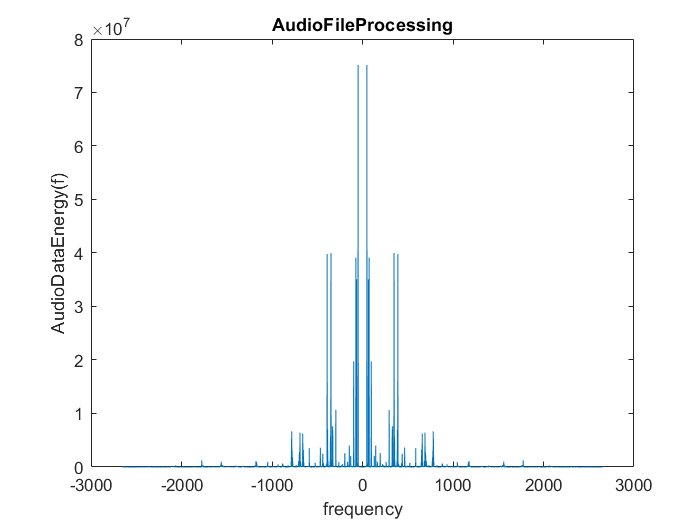

cutSignal = zeros(1,size(normalizedStartBound,2));
cutSignal(1:end) = powerAbs(startBound:endBound);
figure
plot(normalizedStartBound,cutSignal)
xlabel('frequency');
ylabel('AudioDataEnergy(f)');
title('AudioFileProcessing');

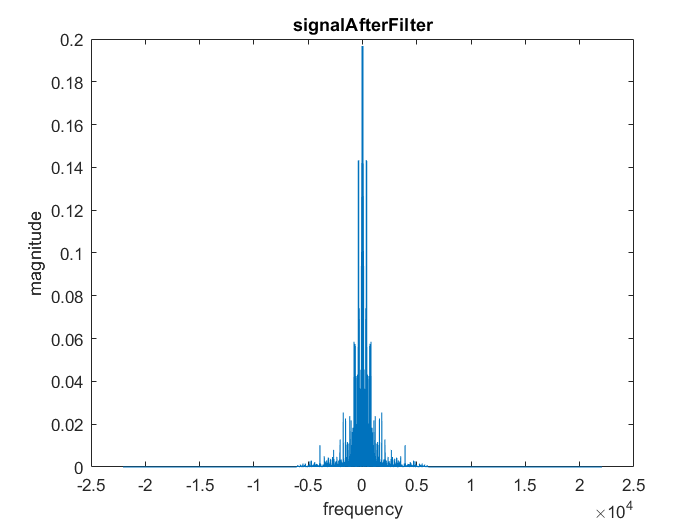

% finding good fm
% playing original voice
sound(signal,fs);

% for i = 1:20
%     SignalBW
%     test = lowpass(signal,SignalBW+i*250 ,fs);
%     sound(test,fs);
% end
% my Deaf ear's Best suggestion :

test = lowpass(signal,6000,fs);
sound(test,fs);

% lowpass with F_cut = SignalBW = 2.6k
test = lowpass(signal,SignalBW,fs);
sound(test,fs);

% filtering signal with real lowpass filter that we designed
load('lowPassFm.mat');
signalFilter = filter(lowPassFm,1,signal);
sound(signalFilter,fs);
[filteredSignal,freq] = standardFourierTransform(signalFilter,fs);
plot(freq,abs(filteredSignal));
title('signalAfterFilter');
xlabel('frequency');
ylabel('magnitude');

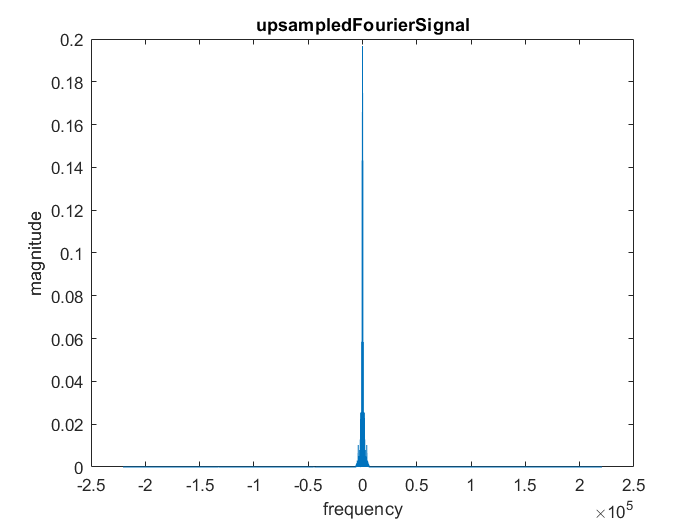

% upsampeling filtered signal
upsampling = 10;
Fs = fs*upsampling;
upsampledSignal = interp(signalFilter,upsampling);
[upsampledSignalFourierTransform,frequency] = standardFourierTransform(upsampledSignal,Fs);
plot(frequency,abs(upsampledSignalFourierTransform));
title('upsampledFourierSignal');
xlabel('frequency');
ylabel('magnitude');

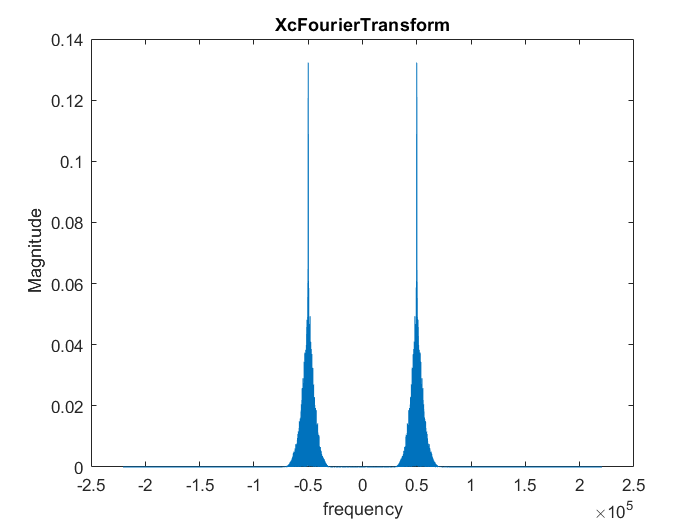

% creating modulated signal
t = 1/Fs:1/Fs:length(upsampledSignal)/Fs;
signalIntegral = Integral(upsampledSignal,Fs);
fm = 6500;
max_signal = max(upsampledSignal);
B = 3;
fc = 50000;
fdelta = B*fm/max_signal;
Xc = cos(2*pi*fc*t + 2*pi*fdelta*signalIntegral);
[XcFourierTransform,freq] = standardFourierTransform(Xc,Fs);
plot(freq,abs(XcFourierTransform));
title('XcFourierTransform');
xlabel('frequency');
ylabel(' Magnitude');

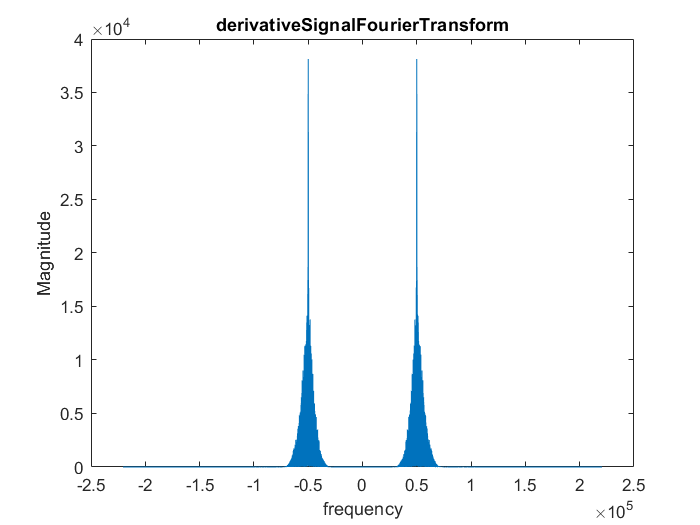

% demodelig signal
derivativeSignal = derivative(Xc,Fs);
[derivativeSignalFourierTransform,freq] = standardFourierTransform(derivativeSignal,Fs);
plot(freq,abs(derivativeSignalFourierTransform));
title('derivativeSignalFourierTransform');
xlabel('frequency');
ylabel('Magnitude');

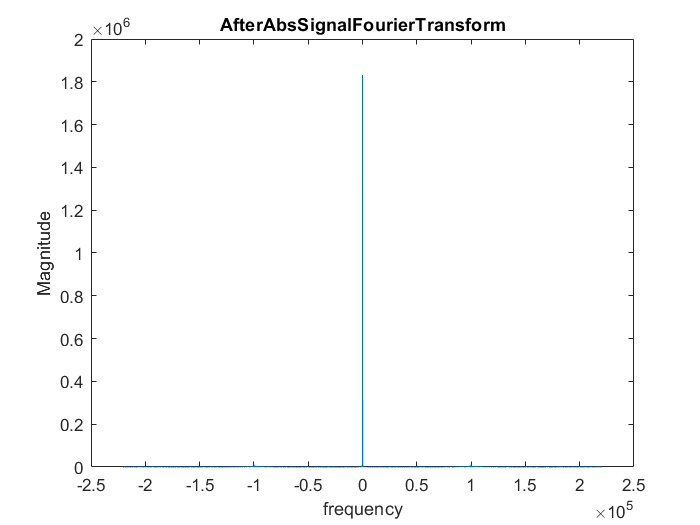

signalabs = abs(derivativeSignal);

[signalAbsFourierTransform,freq] = standardFourierTransform(signalabs,Fs);
plot(freq,abs(signalAbsFourierTransform));
title('AfterAbsSignalFourierTransform');
xlabel('frequency');
ylabel('Magnitude');

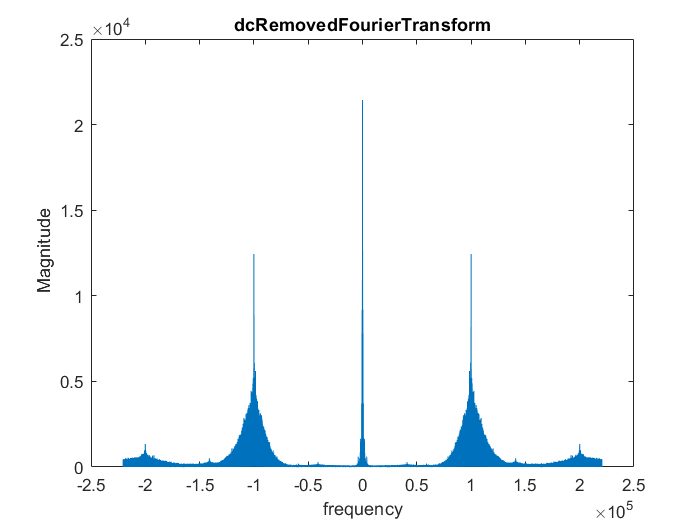

dcBlocker = dsp.DCBlocker;
dcRemovedSignal = dcBlocker(transpose(signalabs));
[dcRemovedFourierTransform,freq] = standardFourierTransform(dcRemovedSignal,Fs);
plot(freq,abs(dcRemovedFourierTransform));
title('dcRemovedFourierTransform');
xlabel('frequency');
ylabel(' Magnitude');

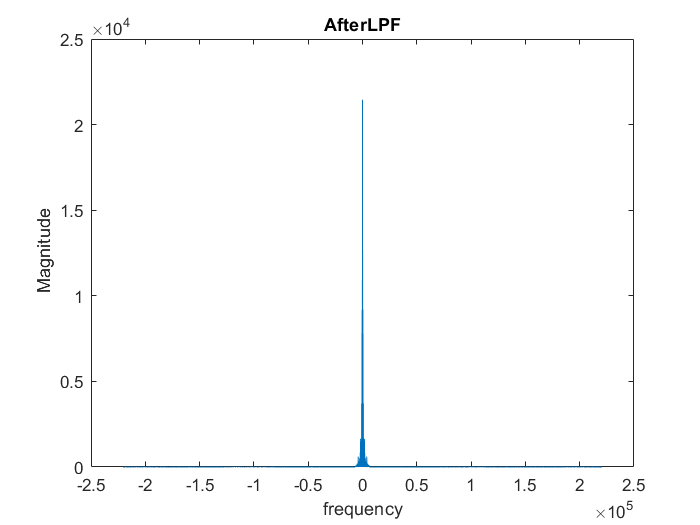

% filtering demodulated
load('DemodLPF.mat');
demodulatedSignal = filter(DemodLPF,1,dcRemovedSignal);
[demodulatedFourierTransform,freq] = standardFourierTransform(demodulatedSignal,Fs);
plot(freq,abs(demodulatedFourierTransform));
title('AfterLPF');
xlabel('frequency');
ylabel(' Magnitude');

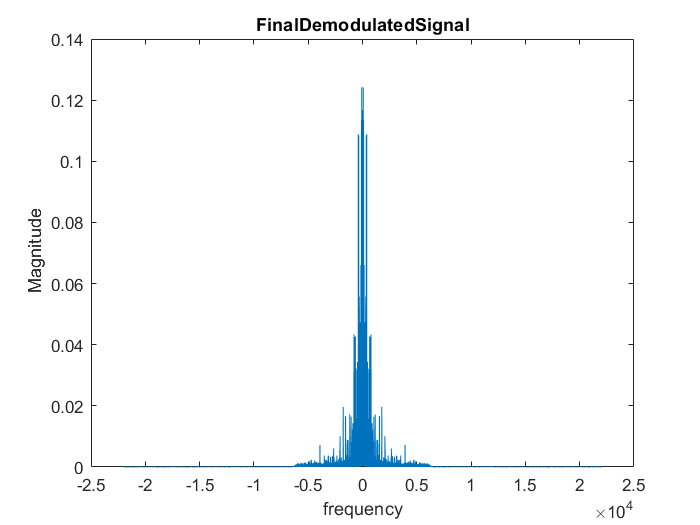

% downsampling signal ...
demodulatedDownSample = downsample(demodulatedSignal,upsampling);

gain = 1/(4*fdelta);
% removing DC 
demoduleDCLess = dcBlocker(demodulatedDownSample);
demoduleDCLess = gain*demoduleDCLess;
[demoduleDCFourierTransform,freq] = standardFourierTransform(demoduleDCLess,fs);
plot(freq,abs(demoduleDCFourierTransform));
title('FinalDemodulatedSignal');
xlabel('frequency');
ylabel(' Magnitude');

sound(demoduleDCLess,fs);
DemoduleVsInputError = immse(abs(signalFourierTransform),abs(demoduleDCFourierTransform))

DemoduleVsInputError = 2.6320e-06

function [out,standardDomain] = standardFourierTransform(signal,fs)
n = length(signal);
fourier=fft(signal,n);
fourier = fourier/fs;
out = fftshift(fourier);
domain = linspace(-pi,pi,length(out));
standardDomain = domain*fs/(2*pi);
end

function [out,Tsignal] = sdf(signal)
Tsignal = fourierDiscreteStandardTransform(signal);
out = Tsignal.*conj(Tsignal);
end

function out = fourierDiscreteStandardTransform(signal)
out = fftshift(fft(signal,size(signal,2)));
end

function boundedEnergy = calEnergy(powerSignal,center,range)
boundedEnergy = sum(powerSignal(center-range:center+range));
end


function integral = Integral(signal,fs)
integral = zeros(1,length(signal));
for i = 2 : length(signal)
    integral(1,i) = integral(1,i-1) + ( signal(i) + signal(i-1) )/(2*fs);
end
end


function derive = derivative(signal,fs)
derive = zeros(1,length(signal));
for i=2:length(signal)-1
    derive(i) = (signal(i+1)-signal(i-1))*fs/2;
end
end